**Technical Prerequisites**

For solving this assignment some additional packages are necessary that are pre-installed on Retina VMs. If you are not working on a Retina machine, install the ROS Gazebo control packages before starting with this lab by executing the following command in a terminal:

Download the ROS meta-packages `simulator`, `system` and `topics_setup` from the Moodle workspace and paste them into the src folder of your `catkin_ws`. The meta-packages contain a lightweight 2D Racecar simulator and some additional messages and packages for running this assignment. Change the permission rights of the python scripts and build the package using

Make sure `catkin_make` finishes without any errors. 

#### Bicycle Kinematic Model

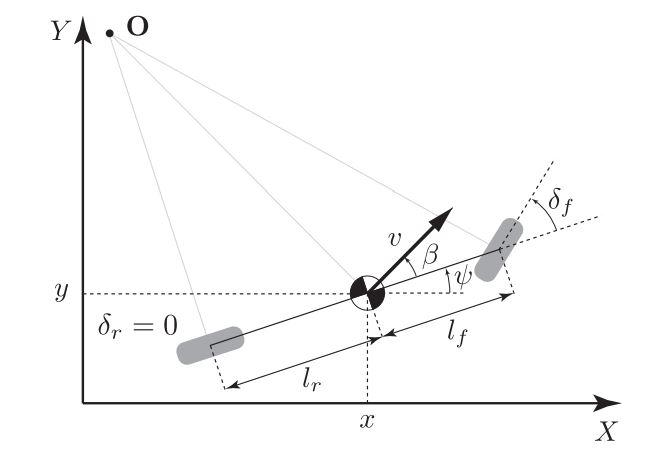

Assume a vehicle with front wheel steering. In the kinematic bicycle model the front wheel represents the left and right front wheel of the actual car, the rear wheel its left and right rear wheel. The bicycle model is depicted in the figure above. The point $$(x,y)$$ located on the line connecting the centers of the rear axle $$(x_r,y_r)$$ and front axle $$(x_f,y_f)$$ denotes the vehicle's center of gravity (COG).

Notice that the direction of the velocity vector $$v$$ at the center of gravity is different from the velocity vectors at the rear wheel $$v_r$$ (direction $$\psi$$) and at the front wheel $$v_f$$ (direction $$\psi+\delta_f$$). 

The angle $$\beta$$, termed (side) slip angle, is the difference between the velocity vector at the COG and the heading of the bicycle $$\psi$$.

The bicycle kinematic model is described by


$$\dot x = v \cos(\psi+\beta)  \\
\dot y = v \sin(\psi+\beta) \\
\dot \psi = \frac{v \cos(\beta) \tan(\delta_f)}{l_r+l_f} \\
\beta = \textrm{atan}( \frac{l_r}{l_f+l_r} \tan(\delta_f)) \approx \frac{l_r}{l_f+l_r} \delta_f$$


in which$ $x,y,\psi$$ are the coordinates and orientation of the vehicle center of mass w.r.t. a global frame. Notice, that the orientation is described by $\psi$ compared to the usual symbol for the orientation of the robot $\theta$ for the sake of consistency with the bicycle model. $$v$$ denotes the vehicle translational velocity and $$\delta_f$$ denotes the steering angle. The geometric parameters $$l_f,l_r$$ represent the distance from the vehicle center to the front and rear axles. The angle $$\beta$$ denotes the direction of the current velocity of the center of mass w.r.t. the longitudinal axis of the car.

The equation for $$\beta$$ is obtained from the no slip condition at the front and rear wheel. For small steering angles $$\delta_f \approx 0$$ the slip angle$ $\beta$$ is equal to the ratio of $$\frac{l_r}{l_r+l_f}$$ times the steering angle $$\delta_f$$. For the two extreme cases $$l_r=0 \rightarrow \beta=0$$ and $$l_f=0 \rightarrow \beta=\delta_f$$.

The solution for $$\dot \psi$$ is obtained from the observation $$\omega=\dot{\psi} =\frac{v}{R}=\frac{v \cos(\beta) \tan(\delta_f)}{l_r+l_f}$$ in which $$R$$ denotes the distance between the COG and the instantaneous center of rotation $$O$$.

The function (given at the end of this script)

implements the bicycle model to simulate simplified car-like vehicle kinematics and dynamics.

The function takes as input arguments the state vector `x`, the control input vector `u` as well as the geometric parameters `lf` and `lr`. The model utilizes vehicle speed $$v$$ and steering angle $$\delta_f$$ as input. It computes the time derivative states according to the bicycle kinematic model equations described above.

The code given in this template generates a bicycle model object which geometric parameters correspond to the F1/10 racecar and simulates an open loop steering at constant velocity $$v_0=3$$ m/s and constant steering angle $$\delta_0=\pi/6$$ rad for $$T_f$$ seconds. The integration time is the actual elapsed time interval between consecutive loop iterations rather than the nominal sample time $$Ts$$. That way the simulation provides for overruns of the rate object, in which the computations are not completed within the sample time.

The helper function 

visualizes the bicycle at pose $$\mathbf{x}=[x \ y \ \psi ]$$ with the steering angle $$\delta_f$$ from $$\mathbf{u}=[v \ \delta_f]$$.

1) Modify the open loop simulation such that the steering angle linearly increases from to  over the course of the simulation by manipulating the steering angle  (which corresponds to the second element of u). The time  corresponds to the variable TNow.

#### Matlab / Gazebo Simulation

T*his section establishes the communication between Gazebo and Matlab. Motion commands in Matlab are published on the corresponding topics for velocity and steering in ROS and passed on to the Gazebo simulation. Gazebo simulates the motion of the F1/10 car in the Gazebo environment and publishes the vehicle pose. Launch the race car simulation using*

*The overall task of controlling and navigating the car along the racetrack is broken down into smaller subtasks, which are further described in the following tasks:*

- *Subscribing to the desired sensors like for example the lidar *

- *Subscribe to the topics which return the vehicle's current position*

- *Generating an empty message to be sent through the publisher*

- *Car parameters*

- *Pure Pursuit Controller initial Parameters *

- *While Loop that calculates and publishes through the empty message the velocity commands.*

*Code for setting up the publisher and subscriber for the Gazebo simulation*

*The *`controlMsg`* is of message type *`ackermann_msgs/AckermannDriveStamped`*. It contains the field *`Drive`* where the *`Speed`* and *`SteeringAngle`* of the vehicle can be set.*

*Use the string *`simulatorType`* for switching between the Matlab *`ode`* function of the bicycle model *

*and the corresponding interaction with the Gazebo simulation:*

2) Initialize the ROS connection and the ROS publishers and subscribers as described above.

3) Send the constant velocity  and the from to  linearly changing steering angle to the Gazebo simulation. Record the vehicle pose and compare the path with the Matlab simulation. Paste a screenshot comparing both pathes here.

#### Clothoids 

*A vehicle that travels along a circular path is subject to a constant lateral acceleration. Assume a road transition from a straight line segment onto a circular arc. Such a path requires a discontinuous change of the steering angle and an abrupt change in lateral acceleration at the tangent point. The first effect requires a complex maneuvering of the driver, the second causes discomfort to the passengers. Therefore road layouts are designed such that the road (path) curvature $\kappa$ changes in a continuous fashion. *

*The so called arc length parametrization parameterizes the curvature of a path *$\kappa \left(s\right)$* by the path length *$s$*.  For a clothoid curve, also known as Euler spiral or Cornu spiral the curvature *$\kappa(s) = \kappa_0 + d \kappa_0 s$* changes linearly with the arc length. The radius of the curve is given by *$\rho(s)= \frac{1}{\kappa(s)}
$*. The straight line is a special case of a clothoid with *$$\kappa(s)=0$
$*. The general relationship between the arc length representation *$\kappa \left(s\right)$* and the Cartesian space is given by:*


$$x(s) = x_0 + \int_{0}^s \cos(\theta(s')) ds'$$



$$y(s) = y_0 + \int_{0}^s \sin(\theta(s')) ds'$$



$$\theta(s) = \theta_0 + \int_{0}^s \kappa(s')) ds'$$


*The equation for *$\theta \left(s\right)$* is obtained from the relationship between the arc length *$s$*, *$ds = \rho \, d\theta$* of a circular arc *$d\theta$* of radius *$\rho$*. The figure below illustrates three clothoids with different parameters *$\kappa_{0\ldotp } ,d\kappa_0$*.*

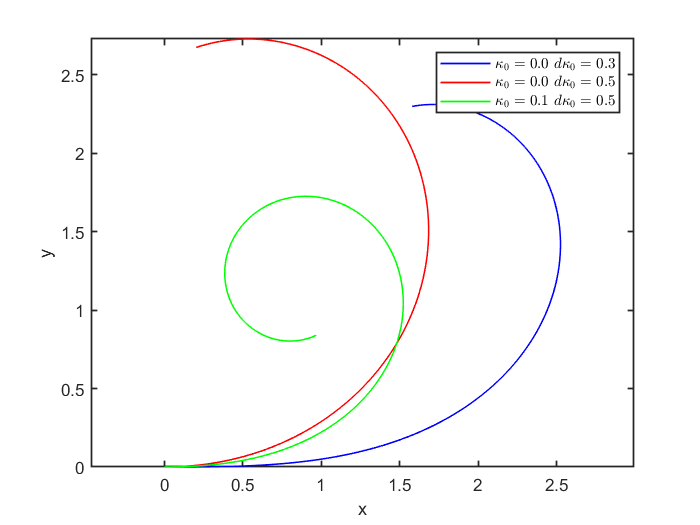

*In general there are no closed form solutions for the integral that calculates *$\theta \left(s\right)$*. In case of a clothoid the relationship between the tangent line orientation *$\theta \left(s\right)$* and curvature is given by *$\theta(s) = \kappa_0 s +  d \kappa_0 \frac{s^2}{2} $*.*

*The relationship for the position *$x(s), y(s)
$* of a clothoid is established by the so called Fresnel integrals.*

*Matlab provides an internal function that computes the Fresnel integrals for a clothoid.*

*in which *$z = \int_0^s e^{i (\kappa_0 s' + d \kappa_0 \frac{s\prime^2}{2} + \theta)} ds'$* in which *$$\kappa_0, d \kappa_0, \theta$$* are scalar constants and *$s$* is a real array.*

$z$* is complex number with *$$x=\textrm{Re}({z}), \ y=\textrm{Im}({z})$$

*These calculations are done in the provided *`Path`* class. *

#### Path Descriptions with Clothoids

*A complete track is defined as a sequence of consecutive clothoids, in which the next clothoid starts at the end of the previous clothoid. The class object *`Path`* defined in *`Path.m`* provides an implementation for track composition from clothoids.*

*The path is constructed from a sequence of clothoids defined by the parameters *$$s_i, {\kappa_0}_i, d {\kappa_0}_i$$*, in which *$$s_i$$* denotes the length of the *$i$*-th clothoid segment *$${\kappa_0}_i$$* initial curvature and the optional parameter *$$d {\kappa_0}_i$$* (default *$0$*) rate of change of curvature. The optional parameter *`initialPose`* defines the start pose of the track with the default value*$[0 \ 0 \ 0]$*.*

*The following code instantiates and visualizes an oval track composed of two straight line segments (length *$$s=10$$* , *$$\kappa_0=0$$*) and two semi-circles (length*$ s=\pi \, R$*, *$$\kappa_0=1/R$$*)*

*The following code instantiates and visualizes a more complex track composed of ten clothoids of variable curvature, including S-shaped segments (change of sign of curvature).*

*The circles in the plot mark the start and end of segments. The following command determines the clothoid that connects the final pose of the last segment with the initial pose of the first segment and adds this segment to the path in order to close the loop. *

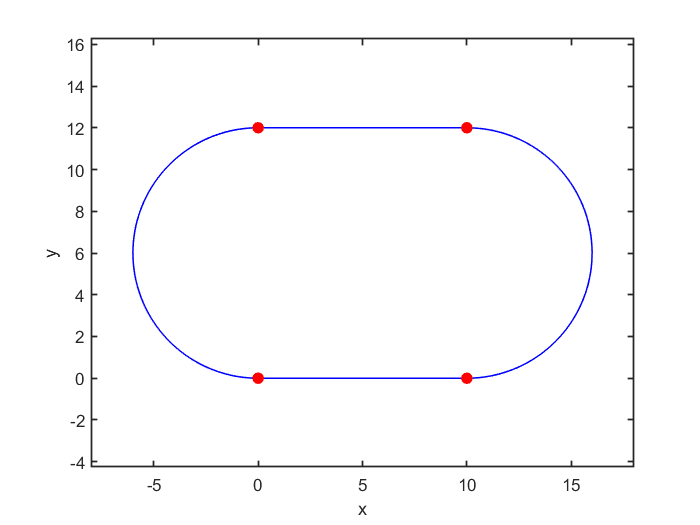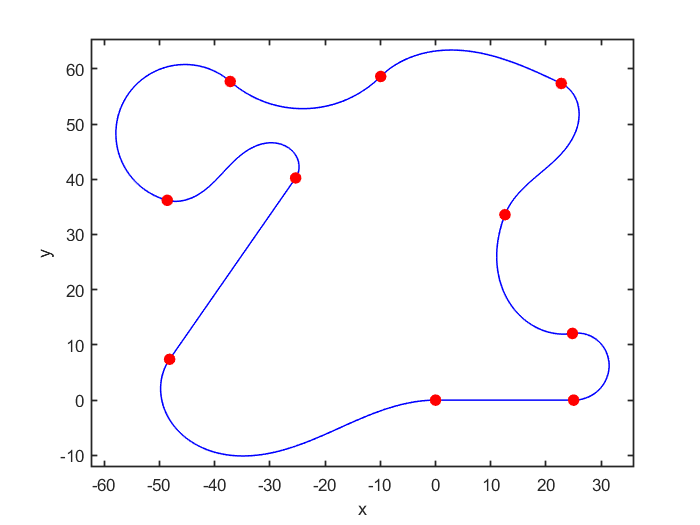

4) Instantiate the oval track path and visualize it in Matlab. The oval track can be launched in the Gazebo simulation using the command:

5) Instantiate the complex track path and visualize it in Matlab. The complex track can be launched in the Gazebo simulation using the command:

6) (Optional) Instantiate your own race track path from a sequence of clothoids, close the track and visualize it in Matlab.

#### Spatial Formulation

*The next task is concerned with tracking a reference path composed of a sequence of clothoids. The spatial reformulation expresses the error between the vehicle pose and the reference path w.r.t. a path centric frame rather than a global frame.*

*The curvature of the reference path is given by *$$\kappa^\sigma$$*.The curvature *$$\kappa^\sigma(s)$$* and poses *$$[X^\sigma(s), \ Y^\sigma(s), \ \psi^\sigma(s)]$$* of the reference path are parameterized in terms of  path length *$ $s$$*. *

*The member function *

*of the class *`Path`* maps the path length *$s$* onto the local curvature of the reference path *$$\kappa^\sigma(s)$$*.*

*The member function*

*maps the path length *$s$* onto the global pose of the reference path *$$[X^\sigma(s), \ Y^\sigma(s), \ \psi^\sigma(s)]$$* .*

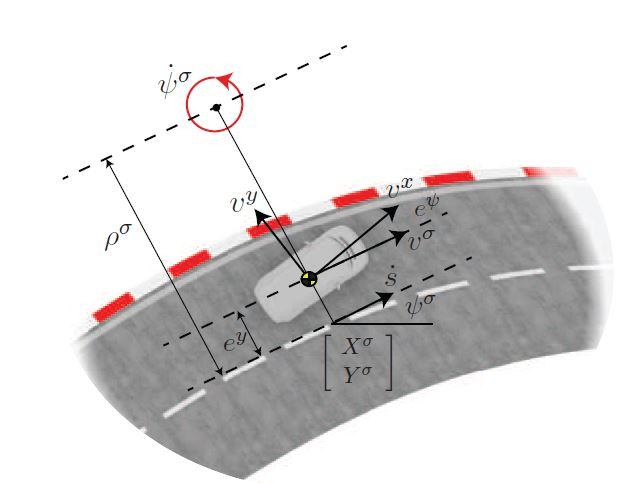

*The Figure above illustrates the spatial relationship between the reference path frame  *$$[X^\sigma, \ Y^\sigma, \ \psi^\sigma]$$* and the vehicle frame *$$[X, Y, \ \psi]$$*.*

*The lateral error *$$e^y$$* and the orientation error *$$e^\psi$$* (not to be confused with the exponential function) are defined by*


$$e^y = \cos(\psi^\sigma) (Y-Y^\sigma) - \sin(\psi^\sigma)(X-X^\sigma)$$



$$e^\psi = \psi - \psi^\sigma$$


*where *$$[X^\sigma, \ Y^\sigma, \ \psi^\sigma]$$* are the position and orientation of the reference point on the path at *$s$*.*

*The member function *

*determines the path relative pose error vector *$$\mathbf{e}=[e^y \; e^\psi]$$* between the current robot pose *`pose`* and the reference pose at pathlength *$s$*.*

*The lateral and orientation error provide the input signal for a feedback control law.*

*The spatial reformulation introduces a new state vector *$$\Xi=[e^y(s) \ e^\psi(s) \ t(s)]$$*. The role of time *$t$* and path length *$s$* are reversed, in the spatial reformulation *$s$* becomes the independent variable and time *$t\left(s\right)$* becomes the dependent state.*

*Applying the spatial formulation to the kinematic equations of the bicycle model described at the beginning of this assignment reveals:*


$$e^{y'}(s) = (v \sin(e^\psi) + v \frac{l_r}{l_f+l_r} \delta_f  \cos(e^\psi))/\dot s$$



$$e^{\psi'}(s) = \frac{\dot \psi}{\dot s}  - \kappa^\sigma(s)$$



$$t'(s) = \frac{1}{\dot s}$$


*with the inputs *$$u=[v \ \delta_f]$$*.*

*The velocity along the path is given by:*


$$\dot s = \kappa^\sigma \dot \psi = \frac{1}{1-e^y/\kappa^\sigma}(v \cos(\beta) \cos(e^\psi) - v \sin(\beta) \sin(e^\psi))$$


*For small slip angles *$$\beta$$* the path velocity *$$\dot s$$* can be approximated by:*


$$\dot s = \kappa^\sigma \dot \psi = \frac{1}{1-e^y/\kappa^\sigma}(v  \cos(e^\psi) - v  \frac{l_r}{l_f+l_r} \delta_f \sin(e^\psi))$$


*The vehicle pose in the global frame is recovered from *$$e^y, \ e^\psi, \psi$$* according to:*


$$X = X^\sigma -e^y \sin(\psi^\sigma)$$



$$Y = Y^\sigma -e^y \cos(\psi^\sigma)$$



$$\psi = \psi^\sigma + e^\psi$$


#### Path Following

*In mere path following the longitudinal velocity *$$v$$* is kept constant and the steering angle *$$\delta_f$$* regulates the lateral and orientation error w.r.t. a lookahead point on the reference path. *

*The objective is to regulate the lateral and orientation error with a proportional controller at a constant velocity.*

*Path following control law with *$$v=\textrm{const}$$*:*


$$\delta_f = - k_y e^y - k_\psi e^\psi$$


*The feedback control in the previous equation is embedded into a rated loop, in which the bicycle kinematic model is numerically integrated according to the current state *$x$* and control *$u$*. *

*An advanced control scheme anticipates the track curvature and incorporates the equivalent steering angle as a feedforward action:*


$$\delta_f = - k_y e^y - k_\psi e^\psi + \Delta \delta_{ff}$$


*The steering angle feedforward action *$$\Delta \delta_{ff}$$* in the equation above corresponds to a circular path of curvature *$\kappa$*:*


$$\Delta \delta_{ff} = \textrm{sgn}(\kappa(s)) \textrm{tan}^{-1}\left(\sqrt{\frac{l_f^2 \kappa(s)^2}{1 - l_r^2 \kappa(s)^2}}\right)$$


7) Implement the path following feedback controller according to the path following control law described above ($\delta_f = - k_y e^y - k_\psi e^\psi$) and observe the tracking error.

8) Augment the path following controller with a feedforward action according to the advanced control scheme described above ($\delta_f = - k_y e^y - k_\psi e^\psi + \Delta \delta_{ff}$). What is the effect on the tracking error?

9) Repeat both previous steps while using Gazebo for simulating the vehicle motion. Record the vehicle pose and compare the path with the Matlab simulation. Test the path following controller for the oval as well as the complex track. Paste Screenshots and comment your comparison below.

% 

#### Trajectory Tracking

*In trajectory tracking the path description is augmented with a timing law, such that the reference path length *$$\hat{s}(t)$$* becomes a function of time *$t$*. The longitudinal velocity remains no longer constant as in path following but regulates the path length error:*


$$e^s=s - \hat{s}$$


*The control law for the longitudinal velocity is given by:*


$$v = -k_s e^s + \hat{\dot{s}}$$


*in which *$$\hat{\dot{s}}$$* denotes the reference path velcocity. We assume a constant reference velocity *$$\hat{v}= 3$$* m/s for trajectory following such that:*


$$\hat{\dot{s}} = \hat{v}\\
\hat{s} = \hat{v} t$$


*In the Matlab code the constant velocity *$$v_0$$* is replaced by the control law for the longitudinal motion:*

**10)** Augment the path following controller to a trajectory tracking controller by replacing v0 in u = [v0 deltaf] with the longitudinal motion control law described above ($v = -k_s e^s + \hat{\dot{s}}$)

#### Kinodynamic Constraints

The kinematic bicycle model ignores the vehicle dynamics, in particular the forces required to guide the vehicle along the trajectory. Constraints are categorized into:

- input constraints on $$v, \delta_f$$, in particular limits of absolute steering angle, maximum velocity, steering rate and maximum acceleration and deceleration:                                                                                                                                                                                                        $	v_{min} \leq v \leq v_{max}\\
	a_{min} \leq \dot v \leq a_{max} \\
	\delta_{min} \leq \delta_f \leq \delta_{max}  \\
	\dot{\delta}_{min} \leq  \dot \delta_f \leq \dot{\delta}_{max} \\$

- geometric constraints, in particular non-violation of track limits $$|e^y| < w(s)$$ in which $$w(s)$$ denotes the lanewidth at path lenght $$s$$

- dynamics constraints (physics of driving), in particular the limitation of lateral acceleration (forces) in turns that need to be balanced by the tire friction forces. The maximum lateral acceleration compensated by friction is given by $	|a_{lat_{max}}| = \mu g $  in which $$\mu \in [0,1]$$ denotes the static friction coefficient and $$g=9.81 m/s^2$$ the gravity acceleration. The centrifugal acceleration of the car in a curve is related to the path velocity and the curvature by	$	a_{lat} =  \frac{v^2}{R} = \frac{v^2 \delta_f}{l_r+l_f} $ in which $$R$$ denotes the radius of the curve. Combining the both equations for the maximum lateral acceleration and the centrifugal acceleration of the car imposes a limit on the maximum velocity $	|v_{max,dyn}| \leq  \sqrt{\frac{\mu g (l_r+l_f)}{|\delta_f|}}$

We merely impose the lateral acceleration constraint. For a more sophisticated approach the kinodynamic and geometric constraints can be considered within a model predictive control framework.

11) Modify the code such that the maximum velocity is limited to the dynamics constraints ($	|v_{max,dyn}| \leq  \sqrt{\frac{\mu g (l_r+l_f)}{|\delta_f|}}$). Furthermore, assure that the overall maximum velocity $$v_{max}$$ is limited to $v_{\max } =10$ m/s.

12) Increase the reference velocity  and observe until which maximum reference velocity the car is able to keep track despite having to slow down in turns. Comment your findings below.

% 

### Code

close all;

% Switch Tasks
simulatorType = 'matlab';   % matlab, gazebo
controlType = 'linear';     % linear, path, trajectory
trackType = 'oval';         % oval, complex, custom
feedforwardControl = true;  % true, false

% Kinematic bicycle model
lr = 0.2;           % distance from geometric center to front axle
lf = 0.2;           % distance from geometric center to rear axle
kinematicModel = bicycleKinematics('Wheelbase',lr+lf, ...
                                   'MaxSteeringAngle', pi/4, ...
                                   'VehicleSpeedRange', [0 20]);

Ts = 0.1;           % sample time
Tf = 20;            % simulation time
v0 = 3;             % constant velocity in m/s
vmax = 10;          % maximum velocity in m/s
delta0 = pi/6;      % constant steering angle
u = [v0 delta0];    % v delta_f

X = [];             % history of poses
U = [];             % history of controls

x0 = [0 0 0];       % pose from the previous step
s0 = 0;             % path length from the previous step

ky = 0.1;           % gain for lateral error
kpsi = 0.3;         % gain for orientation error
ks = 0.5;           % gain for longitudinal error

TLast = 0;

if strcmp(simulatorType, 'gazebo')
    % Task 2)
    % rosinit
        
    % velocity and theta publisher controlPub for topic /control_command
    
    % Set speed and steering angle to zero and send message
    
    % Gazebo car pose subscriber carPoseSub for topic /vesc/odom
    
    % publisher setPosePub for topic /gazebo/set_model_state
    
    % Fill setPoseMsg with the initial pose x0 with the function Pose2SetPoseMsg

end


switch trackType
    case 'oval'
        % Task 4)
        % Define oval track

    case 'complex'
        % Task 5)
        % Define complex track
        
    case 'custom'
        % Task 6) (optional)
        % Define custom track
end

track.plot();

figure;
clf;

rateObj = robotics.Rate(1/Ts);
rateObj.reset;
while (rateObj.TotalElapsedTime < Tf)   
    
    TNow = rateObj.TotalElapsedTime;    % timestamp current iterations
    TSim = TNow - TLast;                % time between consecutive iterations
    TLast = TNow;                       % timestamp for previous iteration
    
    switch controlType
        case 'linear'
            % Task 1) Modify the input u such that the steering angle u(2)
            % increases linearly from -delta0 to delta0
            
        case 'path'
            s = track.pose2PathLength(x0, s0); % closest point on path
            s0 = s;
            kappa = track.kappa(s);
            [ey, epsi] = track.poseError(x0, s + v0 * TSim);  % pose error at lookahead point
            
            clf;
            track.plot();
            hold on;
            
            
            if ~feedforwardControl
                % Task 7)
                % define lateral control law

            else
                % Task 8)
                % define lateral control law with advanced control scheme
            end
	
            u = [v0 deltaf]; % compose control input
        
        case 'trajectory'
            % Task 10) copy code from the 'path' tracking case and augment
            % to trajectory tracking by adding velocity information
            
            
            % Task 11)
            % limit velocity to dynamics constraints
            
               
            u = [v, deltaf]; % compose control input
    end
    
 
    
    switch (simulatorType)
        case 'matlab'
            [t,x] = ode45(@(t,x)kinematicsBicycle(x, u, lf, lr), [0 TSim], x0);
            x0 = x(end,:);
        
        case 'gazebo'
            % Task 3)       
            % Fill controlMsg with Speed u(1) and Steering angle u(2) and
            % send the message

            
            % Receive carPoseMsg, convert it with OdometryMsg2Pose and
            % store the pose in x0

    end
    
    
	X = [X; x0];
	U = [U; u];
	plotBicycle(x0, u, lr, lf);
	hold on;
	plot(X(:,1), X(:,2), 'g-');
	hold off;
	axis equal;
	
	waitfor(rateObj);
end	

% Stop Robot if Gazebo is used
if strcmp(simulatorType, 'gazebo')
    controlMsg.Drive.Speed = 0;
    controlMsg.Drive.SteeringAngle = 0;
    send(controlPub, controlMsg);
end

### Helper Functions (predefined)

function plotBicycle(x0, u, lr, lf)
    % Plots the bicycle front and rear wheel and the connecting line
    %
    % Inputs:
    % x: pose x,y, psi
    % u: v, delta
    % lr: distance between center of mass and rear axle
    % lf: distance between center of mass and front axle
    
    x = x0(:,1);
    y = x0(:,2);
    psi = x0(:,3);
    v = u(1);
    delta = u(2);
    
    % plot current vehicle pose
    % plot center line
    quiver(x, y, cos(psi), sin(psi), lr+lf, 'LineWidth', 1, 'MaxHeadSize', 0.0);
    hold on;
    % plot rear wheel
    quiver(x-lr/2*cos(psi), y-lr/2*sin(psi), cos(psi), sin(psi), lr, 'LineWidth', 3, 'MaxHeadSize', 0.2);
    % plot front wheel
    quiver(x+2*lf*cos(psi)-0.5*lf*cos(psi+delta), y+2*lf*sin(psi)- 0.5*lf*sin(psi+delta), cos(psi+delta), sin(psi+delta), lf, 'LineWidth', 3, 'MaxHeadSize', 0.2);  
    hold off;
end


function [xdot] = kinematicsBicycle(x, u, lf, lr)
    % Computes the bicycle kinematic model
    %
    % Inputs:
    % x: pose x, y, psi
    % u: v, delta
    % lr: distance between center of mass and rear axle
    % lf: distance between center of mass and front axle
    
    if (nargin < 3)
        lf = 0.2;
    end
    if (nargin < 4)
        lr = 0.2;
    end
    v = u(1);
    deltaf= u (2);
    psi = x(3);
    beta = atan(lr/(lf+lr)*tan(deltaf)); % slip angle
    xdot = zeros(3,1); % ode expects column vector
    xdot(1) = v*cos(beta+psi);
    xdot(2) = v*sin(beta+psi);
    xdot(3) = v*cos(beta)*tan(deltaf)/(lr+lf);
end


function [ x, y, theta ] = OdometryMsg2Pose( poseMsg )
    % convert odometry message to vector
    %
    % Inputs:
    % poseMsg: ROS pose message
    
    x = poseMsg.Pose.Pose.Position.X;
    y = poseMsg.Pose.Pose.Position.Y;
    eul = quat2eul([poseMsg.Pose.Pose.Orientation.W poseMsg.Pose.Pose.Orientation.X  poseMsg.Pose.Pose.Orientation.Y poseMsg.Pose.Pose.Orientation.Z]);
    theta = eul(1);
end


function setPoseMsg = Pose2SetPoseMsg(setPoseMsg, pose)
    % fills setPoseMsg with pose
    %
    % Inputs:
    % setPoseMsg: ROS setPose message
    % pose: pose x, y, psi

    setPoseMsg.ModelName="racecar";
    
    setPoseMsg.Pose.Position.X = pose(1);
    setPoseMsg.Pose.Position.Y = pose(2);
    quat = eul2quat([pose(3) 0 0]);
    
    setPoseMsg.Pose.Orientation.W = quat(1);
    setPoseMsg.Pose.Orientation.X = quat(2);
    setPoseMsg.Pose.Orientation.Y = quat(3);
    setPoseMsg.Pose.Orientation.Z = quat(4);
end